Estimated BPM: 137.838
    0.7061   -3.4144    0.8074   -0.0105    0.2364    0.0358    0.0435    0.0152    0.0070   -0.0121   -0.0001    0.0127    0.0421    0.0103    1.4194   24.2451    1.4673    0.1296    0.2078    0.0946    0.0653    0.0626    0.0674    0.0635    0.0570    0.0543    0.0629    0.0499    4.5788    2.9593    3.9630    1.3583    1.9171    1.3434    1.0291    1.1953    1.1069    0.9841    1.0272    1.2146    1.0828    1.0204   -1.6570  -14.7195   -1.4289   -1.5397   -1.0988   -1.2096   -1.1737   -1.1693   -1.1850   -1.2700   -1.1272   -1.0531   -0.9380   -1.0096



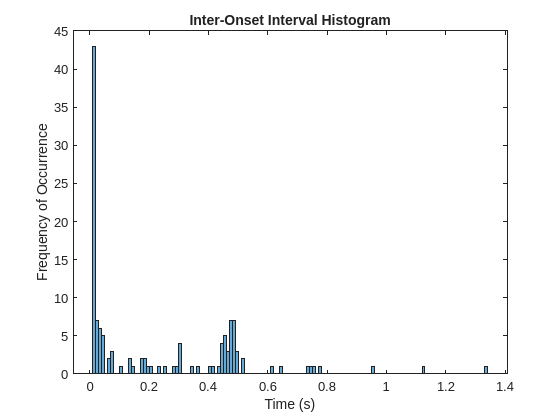

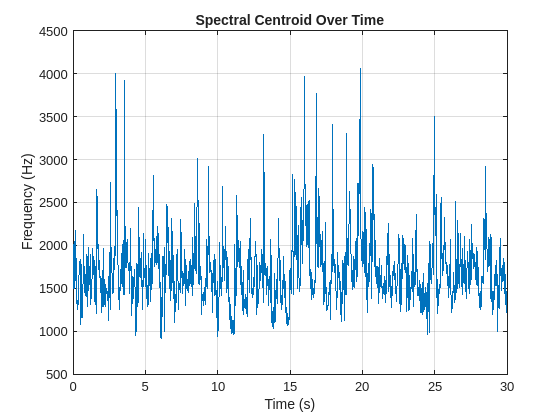

Length of T: 2992
Length of fluxTime: 2991
Length of spectralFlux: 2991
Length of waveletFlux: 661794
Length of F: 513
Length of density: 513
Average Harmonic to Noise Ratio over time: 6.9552 dB
Maximum Harmonic to Noise Ratio: 13.1946 dB at time 0.08517 s
Average Density: 0.0019493
Maximum Density: 0.021783 at frequency 193.7988 Hz
Average Spectral Centroid over time: 1703.671 Hz
Maximum Spectral Centroid: 4059.4779 Hz at time 19.8499 s
RMS Energy: 0.15908


Power of High Frequency Components (Above 3000 Hz): 0.0065624
Power of Low Frequency Components (Below 1000 Hz): 0.02453


x = "Data/genres_original/blues/blues.00000.wav"

clear all;
features = zeros(100, 4000);
x = audioAnalysis("Data/genres_original/blues/blues.00000.wav")

for ii = 0:99
    A = sprintf('Data/genres_original/rock/rock.%05d.wav', ii);
    [y, fs] = audioread(A);
    
    feature = extract_features(y, fs);
    % Extract DSP features
    feature = [feature, zeros(1, length(features)-length(feature))];
    features(ii +1, :) = feature;  % Replace with your feature extraction function

end
for ii = 0:99
    A = sprintf('Data/genres_original/classical/classical.%05d.wav', ii);
    [y, fs] = audioread(A);
    feature = extract_features(y, fs);
    % Extract DSP features
    feature = [feature, zeros(1, length(features)-length(feature))];
    features(ii +101, :) = feature;  % Replace with your feature extraction function
end
for ii = 0:99
    A = sprintf('Data/genres_original/country/country.%05d.wav', ii);
    [y, fs] = audioread(A);
    feature = extract_features(y, fs);
    % Extract DSP features
    feature = [feature, zeros(1, length(features)-length(feature))];
    features(ii +201, :) = feature;  % Replace with your feature extraction function
end
for ii = 0:99
    A = sprintf('Data/genres_original/blues/blues.%05d.wav', ii);
    [y, fs] = audioread(A);
    feature = extract_features(y, fs);
    % Extract DSP features
    feature = [feature, zeros(1, length(features)-length(feature))];
    features(ii +301, :) = feature;  % Replace with your feature extraction function
end


numTrainingDatapoints = 350;
datapoints = randi([1 400], [numTrainingDatapoints 1]);
trainingData = zeros(numTrainingDatapoints, 4000);
for ii = 0:numTrainingDatapoints
    trainingData(ii)
end

Array indices must be positive integers or logical values.

function features = extract_features(audio_signal, sample_rate)
    % Compute the Short-Time Fourier Transform (STFT) using spectrogram
    window_length = 1024;  % Window length for STFT
    overlap = 512;  % Overlap between consecutive windows
    nfft = 1024;  % Number of FFT points
    [~, f, t, S] = spectrogram(audio_signal, hamming(window_length), overlap, nfft, sample_rate);
   
    % Compute spectral features (e.g., mean energy in different frequency bands)
    freq_bins = [0 1000 2000 4000];  % Frequency band edges
    spectral_features = zeros(length(freq_bins) - 1, size(S, 2));  % Initialize feature matrix
    for i = 1:length(freq_bins) - 1
        freq_range_idx = find(f >= freq_bins(i) & f < freq_bins(i + 1));
        spectral_features(i, :) = mean(abs(S(freq_range_idx, :)), 1);
    end
   
    % Flatten the spectral features matrix to a 1D vector
    features = reshape(spectral_features, 1, []);
end